# Exercise 3 

Ambiguity Resolution, Linear combinations & Intrigity 2020/21

Chawda Vimal                                     Mart No-10025862

clc;
clear all;
close all;
format long g;

## Task 1 Concept of Ambiguity Resolutions 

**Task 1.2  **

N_bar = [5.3; 3.4];                  % Flot solution for the ambiguity 
Q_nn_bar = [2.52,2.73;2.73,3.01];    % any from 3.00 to 4.56 (mention)
corre_N = corrcov(Q_nn_bar);         % we are checking the correlation between the floct ambiguity
chi = 1.5;                           % mention in the lecture notes


eigen value decomposition svd

[U,S,D]=svd(Q_nn_bar); 
a=sqrt(S(1,1)*chi);               %semi minor axis
b=sqrt(S(2,2)*chi);               %semi major axis

theta=atan(U(2,1)/U(1,1)); 
% correlation matrix & mention above with corre_N
correlation = corrcov(Q_nn_bar);

% create points for plotting the ellipse
t = linspace(0,2*pi);
ellipspoints(:,1) = N_bar(1) + a*cos(t)*cos(theta) - b*sin(t)*sin(theta);
ellipspoints(:,2) = N_bar(2) + a*cos(t)*sin(theta) + b*sin(t)*cos(theta); 

% find the edges of the rectangular search space
min_x = min(ellipspoints(:,1));
max_x = max(ellipspoints(:,1));
min_y = min(ellipspoints(:,2));
max_y = max(ellipspoints(:,2));

% rectangular 
rectangle = [min_x, min_y; max_x, min_y; max_x, max_y; min_x, max_y; min_x, min_y];

% look for integer values in the rectangle
x_in_rectangle = ceil(min_x):1:floor(max_x);
y_in_rectangle = ceil(min_y):1:floor(max_y);
[X,Y] = meshgrid(x_in_rectangle,y_in_rectangle);
in_rectangle = [reshape(X,1,[])',reshape(Y,1,[])'];
int_rectangle = size(in_rectangle,1);

% put all integer values in together
pointsinellipse = [];
for i = 1:int_rectangle
    R = [cos(-theta), -sin(-theta); sin(-theta), cos(-theta)];
    P = N_bar + R*(in_rectangle(i,:)' - N_bar);
    test = (P(1) - N_bar(1))^2/a^2 + (P(2) - N_bar(2))^2/b^2;
    if test <= 1
        pointsinellipse = [pointsinellipse;in_rectangle(i,:)];
    end
end
inside_ellipse = size(pointsinellipse,1);


Plot the result

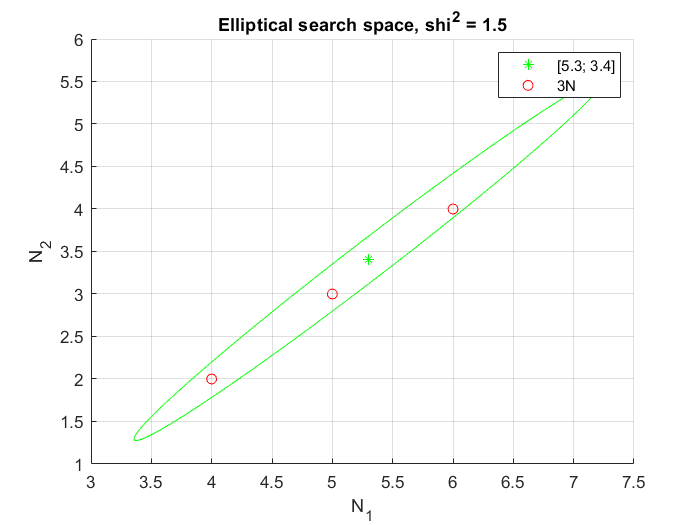

figure()
hold on
% plot reference point N_bar
title('Elliptical search space, shi^2 = 1.5')
plot(N_bar(1),N_bar(2),'*g')
% elliptical search space 
scatter(pointsinellipse(:,1),pointsinellipse(:,2),'r') 
plot(ellipspoints(:,1),ellipspoints(:,2),'g')
grid on
xlabel('N_1')
ylabel('N_2')
legend('[5.3; 3.4]','3N');
hold off

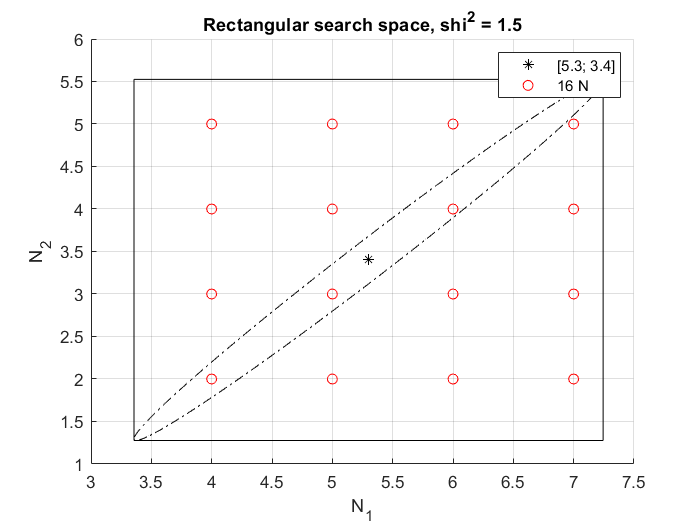


figure()
hold on
% plot reference point
plot(N_bar(1),N_bar(2),'*k') 
% rectangular search space
scatter(in_rectangle(:,1),in_rectangle(:,2),'r') 
% plot ellipse
plot(ellipspoints(:,1),ellipspoints(:,2),'-.k') 
% plot rectangle
plot(rectangle(:,1),rectangle(:,2),'k') 
grid on
title('Rectangular search space, shi^2 = 1.5')
xlabel('N_1')
ylabel('N_2')
legend('[5.3; 3.4]','16 N');
hold off

## 2nd Step of General approach of ambiguity resolutions

for i = 1 : int_rectangle
        Omega_FARA(i,1)=(N_bar-in_rectangle(i,:)')'*Q_nn_bar^-1*(N_bar-in_rectangle(i,:)');
end

sort the points dependent on the best omega, start with the smalles value

[Omega_FARA_sort,index] = sort(Omega_FARA(:,1));

computing the Ratio test value

ratio_test = Omega_FARA_sort(2)/Omega_FARA_sort(1);

 test the ratio

if ratio_test < 3
    disp('FARA - compatibility test passed')
    % fixed ambiguities
    N_FARA = in_rectangle(index(1),:)'; 
else disp('FARA - compatibility test failed')
    % fixed ambiguities
    N_FARA = in_rectangle(index(1),:)'; 
end

FARA - compatibility test failed


## Lamda Method

Define the transformation matrix

find the index(id) of the max element of Q_nn_bar

id = find((diag(Q_nn_bar)) == max(diag(Q_nn_bar)));


if the first ambiguity is less precise

elseif the second ambiguity is less precise

if id == 1 
    Z_T1 = [1, -round(Q_nn_bar(1,2)/Q_nn_bar(2,2)); 0, 1];
    Q_z1 = Z_T1*Q_nn_bar* Z_T1';
    Z_T2 = [1, 0; -round(Q_z1(2,1)/Q_z1(1,1)), 1];
    Q_z2 = Z_T2*Q_z1*Z_T2';
    Z = Z_T2*Z_T1;
elseif id == 2 
    Z_T1 = [1, -round(Q_nn_bar(1,2)/Q_nn_bar(2,2)); 0, 1];
    Q_z1 = Z_T1*Q_nn_bar* Z_T1';
    Z_T2 = [1, 0; -round(Q_z1(2,1)/Q_z1(1,1)), 1];
    Q_z2 = Z_T2*Q_z1*Z_T2'; 
    Z = Z_T1*Z_T2;
end

N_hat1 = Z_T1*N_bar;


create points for plotting the ellipse

 eigenvalues and  eigenvector of Q_z1

[U,S,D] = svd(Q_z1);

 semi-major axis of elli

a=sqrt(S(1,1)*chi);

 semi-minor axis of ellipse

b=sqrt(S(2,2)*chi);
theta=atan(U(2,1)/U(1,1));

t = linspace(0,2*pi);
ellipsepoints_lambda1(:,1) = N_hat1(1) + a*cos(t)*cos(theta) - b*sin(t)*sin(theta);
ellipsepoints_lambda1(:,2) = N_hat1(2) + a*cos(t)*sin(theta) + b*sin(t)*cos(theta);

N_hat2 = Z_T2*N_hat1;


 create points for plotting the ellipse

eigenvalues and  eigenvector of Q_z2

[U,S,D] = svd(Q_z2);

semi-major axis of ellipse

a=sqrt(S(1,1)*chi);

semi-minor axis of ellipse

b=sqrt(S(2,2)*chi);
theta=atan(U(2,1)/U(1,1));
t = linspace(0,2*pi);
ellipsepoints_lambda2(:,1) = N_hat2(1) + a*cos(t)*cos(theta) - b*sin(t)*sin(theta);
ellipsepoints_lambda2(:,2) = N_hat2(2) + a*cos(t)*sin(theta) + b*sin(t)*cos(theta);


 transformed ambiguities

z_hat = Z*N_bar;

figure()
hold on
plot(ellipspoints(:,1),ellipspoints(:,2),'r') 
title('LAMBDA: elliptical search space, shi^2 = 1.5')
legend('original')
axis([-5 15, -10 15]);
xlabel('N1');
ylabel('N2');
grid on


1. transformation

plot(ellipsepoints_lambda1(:,1),ellipsepoints_lambda1(:,2),'g')
legend('original','1st trafo')

2. transformation

plot(ellipsepoints_lambda2(:,1),ellipsepoints_lambda2(:,2),'b')
legend('original','1st trafo','2nd trafo')


plot of the points

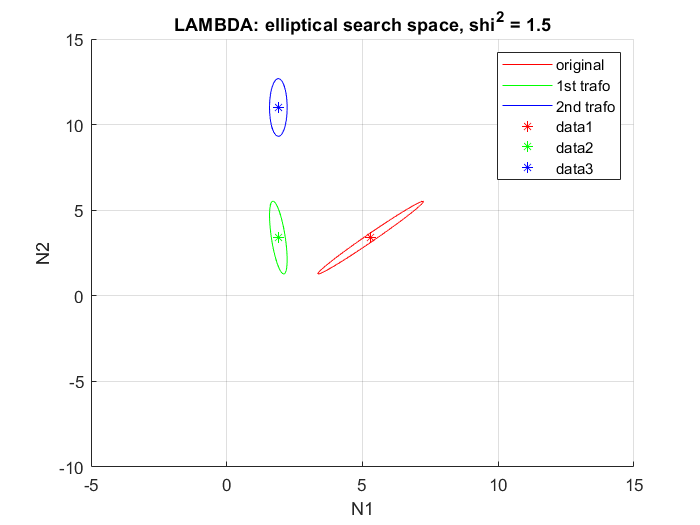

plot(N_bar(1),N_bar(2),'*r')
plot(N_hat1(1),N_hat1(2),'*g')
plot(N_hat2(1),N_hat2(2),'*b')
hold off

change of the estimated coordinates

the given variance-covariance matrices

Q_Nx_hat = [7.5, 16.5, 25.5; 12, 9.5, 20.5]; % [mm]         
Q_xx_hat = [200, 150, 50; 150, 250, 75; 50, 75, 400]; % [mm^2] 

Change of the estimated coordinates

delta_x = -Q_Nx_hat'*inv(Q_nn_bar)*(N_bar-z_hat); % x_fixed - x_float

New variances 

Q_x_fix = Q_xx_hat - Q_Nx_hat'*inv(Q_nn_bar)*Q_Nx_hat;


## task 2.3

f1 = 2*77*10.23*10^6; % [Hz]
f2 = 2*60*10.23*10^6; % [Hz]
c = 3*10^8; %[m/s]

% define the coefficient parameters
alpha = [-100:1:100];
beta = [-100:1:100];

% Compute the basic quantities

for i = 1 : length(alpha)
     j = 1: length(beta)
    Iono(i,j) = ((alpha(i)*f1*f2)+(beta(j)*f1^2))/((f2*((alpha(i)*f1)+(beta(j)*f2))));
    lambda(i,1) = c/((alpha(1,i)*f1)+(beta(1,i)*f2));
    noise(i,1) = sqrt(((alpha(1,i)*f1)/(alpha(1,i)*f1+beta(1,i)*f2))^2+((beta(1,i)*f2)/(alpha(1,i)*f1+beta(1,i)*f2))^2);
    i=i+1
end

i =      2


i =      3


i =      4


i =      5


i =      6


i =      7


i =      8


i =      9


i =     10


i =     11


i =     12


i =     13


i =     14


i =     15


i =     16


i =     17


i =     18


i =     19


i =     20


i =     21


i =     22


i =     23


i =     24


i =     25


i =     26


i =     27


i =     28


i =     29


i =     30


i =     31


i =     32


i =     33


i =     34


i =     35


i =     36


i =     37


i =     38


i =     39


i =     40


i =     41


i =     42


i =     43


i =     44


i =     45


i =     46


i =     47


i =     48


i =     49


i =     50


i =     51


i =     52


i =     53


i =     54


i =     55


i =     56


i =     57


i =     58


i =     59


i =     60


i =     61


i =     62


i =     63


i =     64


i =     65


i =     66


i =     67


i =     68


i =     69


i =     70


i =     71


i =     72


i =     73


i =     74


i =     75


i =     76


i =     77


i =     78


i =     79


i =     80


i =     81


i =     82


i =     83


i =     84


i =     85


i =     86


i =     87


i =     88


i =     89


i =     90


i =     91


i =     92


i =     93


i =     94


i =     95


i =     96


i =     97


i =     98


i =     99


i =    100


i =    101


i =    102


i =    103


i =    104


i =    105


i =    106


i =    107


i =    108


i =    109


i =    110


i =    111


i =    112


i =    113


i =    114


i =    115


i =    116


i =    117


i =    118


i =    119


i =    120


i =    121


i =    122


i =    123


i =    124


i =    125


i =    126


i =    127


i =    128


i =    129


i =    130


i =    131


i =    132


i =    133


i =    134


i =    135


i =    136


i =    137


i =    138


i =    139


i =    140


i =    141


i =    142


i =    143


i =    144


i =    145


i =    146


i =    147


i =    148


i =    149


i =    150


i =    151


i =    152


i =    153


i =    154


i =    155


i =    156


i =    157


i =    158


i =    159


i =    160


i =    161


i =    162


i =    163


i =    164


i =    165


i =    166


i =    167


i =    168


i =    169


i =    170


i =    171


i =    172


i =    173


i =    174


i =    175


i =    176


i =    177


i =    178


i =    179


i =    180


i =    181


i =    182


i =    183


i =    184


i =    185


i =    186


i =    187


i =    188


i =    189


i =    190


i =    191


i =    192


i =    193


i =    194


i =    195


i =    196


i =    197


i =    198


i =    199


i =    200


i =    201


i =    202



figure()
xlim(-100:0:100)
ylim(-100:0:100)
imagesc(Iono)
grid on


## Task 3

**Task 3.2**


k = 15;   % In stud ip it was 15
VPL_k = VPL_total((k*500)-499:1:k* 500); % given formula
VPE_k = VPE_total((k*500)-499:1:k* 500);
time_k = time_total((k*500)-499:1:k* 500);
VAL = 7;                     % meter given


a) VPE < VAL & VPE < VPL    =  Ok

 b) VPE > VAL                          = HMI

c) VPE < VAL & VPE > VPL    = MI

d) VPL > VAL                          = system Unavbl


count_a = 0;
count_b = 0;
count_c = 0;
count_d = 0;

for i=1:1:500
    if VPE_k(i) < VAL && VPE_k(i) < VPL_k(i)
        count_a = count_a + 1;
    elseif VPE_k(i) > VAL
        count_b = count_b + 1;
    elseif VPE_k(i) < VAL && VPE_k(i) > VPL_k(i)
        count_c = count_c + 1;
    elseif VPL_k(i) > VAL
        count_d = count_d + 1;   % system unavailable
    end
end

per_a = count_a / 500;
per_b = count_b / 500;
per_c = count_c / 500;
per_d = count_d / 500;


Plot

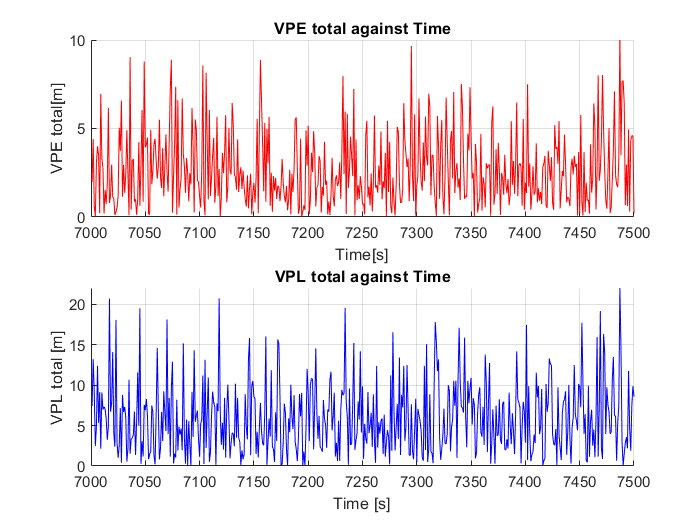

figure()
subplot(211)
hold on
title('VPE total against Time')
plot(time_k,VPE_k,'r')
grid on
ylim([0 10])
xlabel('Time[s]')
ylabel('VPE total[m]')
hold off

subplot(212)
hold on
title('VPL total against Time')
plot(time_k,VPL_k,'b')
grid on
xlabel('Time [s]')
ylabel('VPL total [m]')
hold off

 Plot Stanford 

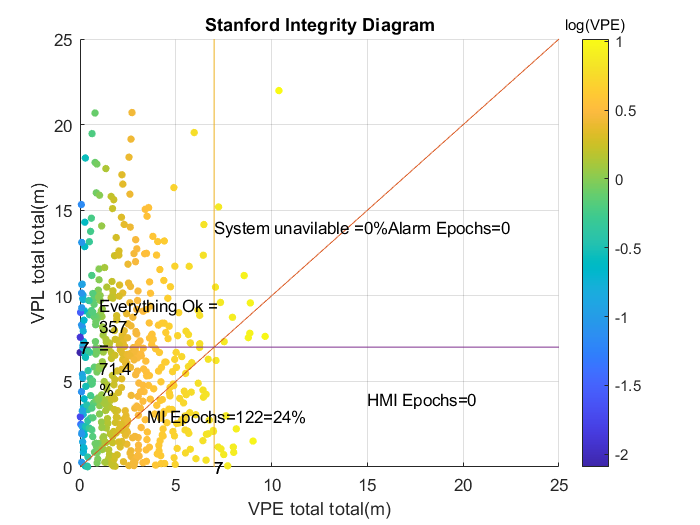

figure()
hold on
title('Stanford Integrity Diagram')
log_VPE_k = log10(VPE_k);
scatter(VPE_k,VPL_k,20,log_VPE_k,'filled'); %scatter plot
plot([0 40],[0 40])
plot([7 7],[0 40])
plot([0 40],[7 7])
t = text(1,7,{'Everything Ok = ',count_a,'=',per_a*100,'%'});
text(7,0,'7')
text(0,7,'7')
text(15,7-3,{strcat('HMI Epochs= ',int2str(0.04))})
text(7/2,3,{strcat('MI Epochs= ',int2str(count_c), '=',int2str(per_c*100),'%')})
text(7,7+7,{strcat('System unavilable = ',int2str(per_d*100),'%','Alarm Epochs','=',int2str(count_d))})
text(7,0,'7')
text(0,7,'7')
cb = colorbar();
title(cb, 'log(VPE)');
grid on
xlim([0 25])
ylim([0 25])
xlabel('VPE total total(m)')
ylabel('VPL total total(m)')
hold off

Task 3.4

For dx

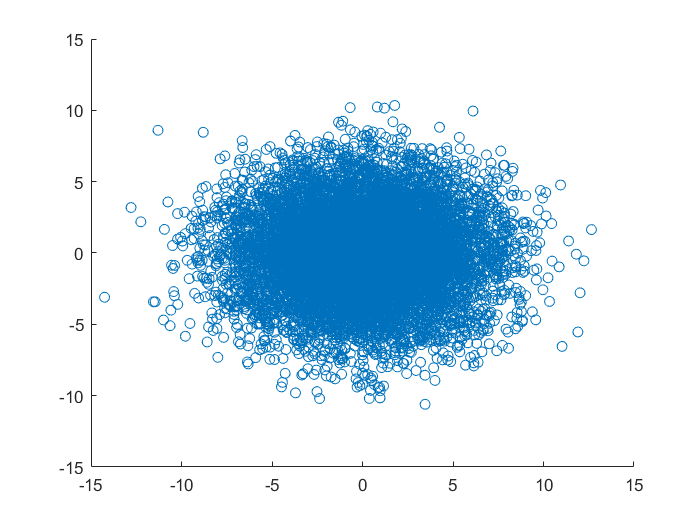

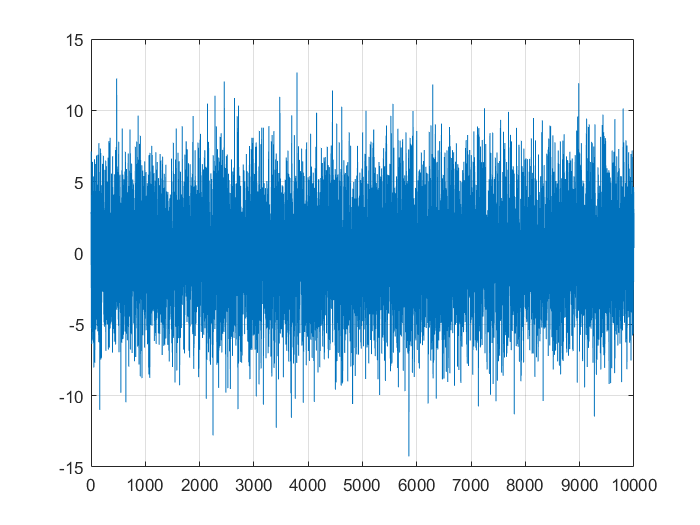

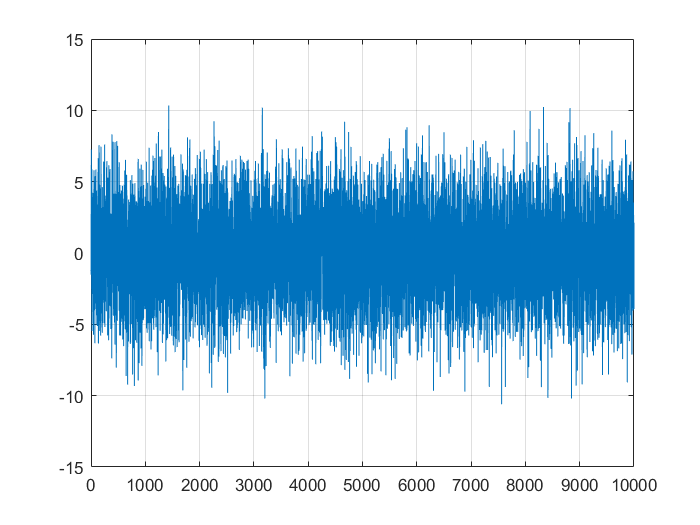

figure()

histogram(dx)


figure()
histogram(dy)

figure()
for i=1:length(dx)
    dxy(i)= sqrt(dx(i)^2+dy(i)^2);
end
histogram(dxy)